## Zadanie 3) Optymalizacja regulatora PD po module

#### a) Optymalizacja bez ograniczeń

Wykorzystując funkcje fminsearch, należy wykonać optymalizację nastaw regulatora PD aby zapas po module był M≥2

gdzie:

obiekt G(s)=1s3+3s2+4s+2

regulator  Gr(s)=Kp+Kds

Przykład

clear
Gs2=tf([1],[1 3 4 2])

Gs2 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



x0 = [1,0,0]; %
fun = @ident;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x,fval,exitflag] = fminsearch(fun,x0,options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          64.0002         
     1            4          56.6079         initial simplex
     2            5          56.6079         reflect
     3            7          52.1609         expand
     4            9          43.0348         expand
     5           10          43.0348         reflect
     6           12          31.0786         expand
     7           14          22.3191         expand
     8           15          22.3191         reflect
     9           17           9.7254         expand
    10           19          5.66257         expand
    11           21           2.6412         expand
    12           23         0.237252         expand


    13           25       0.00362095         expand
    14           26       0.00362095         reflect
    15           28       0.00362095         contract outside


    16           30       0.00362095         contract inside
    17           32       0.00362095         contract outside


    18           34       0.00362095         contract inside
    19           36       0.00196568         contract inside
    20           38       0.00115315         contract inside


    21           40      0.000548182         contract inside
    22           42      0.000548182         contract inside
    23           44      0.000322023         contract inside
    24           46      0.000162726         contract inside
    25           48      0.000133602         contract inside
    26           50      7.68512e-05         contract inside
    27           52      5.47099e-05         contract inside
    28           54      2.14201e-05         contract inside
    29           56      2.14201e-05         contract inside
    30           58      9.59025e-06         contract inside
    31           60      9.59025e-06         contract inside
    32           62      2.77304e-06         contract inside
    33           64      2.77304e-06         contract inside
    34           66      1.08782e-06         contract inside
    35           68      1.08782e-06         contract inside
    36           70      6.25123e-07         contract inside
    37           72     

x =     4.9676    0.0004   -0.0108


fval = 1.5112e-10

exitflag = 1

G1=tf([1],[1 3 4 2]) % System

G1 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



C = pid(x(1),x(2),x(3)) % Controller

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 4.97, Ki = 0.000442, Kd = -0.0108
 
Continuous-time PID controller in parallel form.



%G2=tf([0 1],[x(1) x(2) x(3)])
G1

G1 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



G2_loop=feedback(C*G1,1)

G2_loop =
 
       -0.01084 s^2 + 4.968 s + 0.0004421
  ---------------------------------------------
  s^4 + 3 s^3 + 3.989 s^2 + 6.968 s + 0.0004421
 
Continuous-time transfer function.



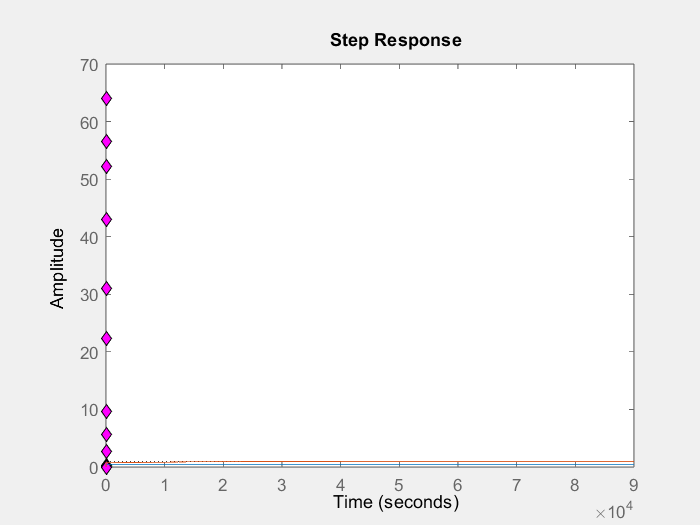

%step(G1);
step(G1,G2_loop);

G2=C*G1;
[Gm,Pm,Wcg,Wcp] = margin(G2);
%Gs=feedback(C*G1,1)
b=G2_loop.Numerator{1, 1};
a=G2_loop.Denominator{1,1};
Gm

Gm = 2.0000

C

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 4.97, Ki = 0.000442, Kd = -0.0108
 
Continuous-time PID controller in parallel form.



[z,p,k] =tf2zp(b,a)

z =   458.2762
   -0.0001


p =   -2.5153 + 0.0000i
  -0.2423 + 1.6466i
  -0.2423 - 1.6466i
  -0.0001 + 0.0000i


k = -0.0108

%Kp = x(1)
%Ki = x(2)
%Kd = x(3)

function blad = ident(x)
t=0:0.01:10;
G1=tf([1],[1 3 4 2]);
C = pid(x(1),x(2),x(3)); % Controller
G2=C*G1;
[Gm,Pm,Wcg,Wcp] = margin(G2);
e = (Gm-2)^2;
blad= e;
end



b)    Optymalizacja z ograniczeniami

Nałożyć ograniczenia na współczynniki dla regulatora rzeczywistego

// Dla zainteresowanych. Z tematyki optymalizacji regulatorów rozszerzonej o lokowanie zer i biegunów można pisać pracę inżynierską.